# Progsheet 2 - Introduction to the Numerics of partial differential equations

*Author: Sven Ullmann and Jonathan Schnitzler*

This is an exercise sheet for Linear FEM.

We create a Trianglulation `[p,e,t]` with `n:=|I| `according to Exercise Sheet 03 from Introduction to the numerics of ordinary differential equations. With the given two meshes we want to solve the poisson problem


$$-\Delta \;u=1\;\;\;\;\textrm{on}\;\Omega \;$$



$$\;\;\;\;\;\;\;\;u=0\;\;\;\;\;\textrm{on}\;\partial \;\Omega \;$$


We will consider **solve **and **adaptive solve**

## a) Poisson initialization

Firstfully we consider what is p, e and t of a triangulation. We will use the `Parial Differential Equation Toolbox `from `Matlab `with important functions such as:

- `initmesh    `- initializes a mesh

- `pdegplot(.) `- plots the geometry (`g`) of the pde

The Triplet `[p,e,t]` is of major importance. They represent the mesh data and the components stand for

#### p - node points:

    Besteht aus x und y daten

    Wird bei bisect beispielsweise um 1 erhöht

#### e - edge assiciativity - Boundary:

Rows:

    1. & 2. indices of starting and ending point, 

      3. & 4. the starting and ending parameter values

      5.        the boundary edge segment number

      6. & 7. left- and right-hand side subdomain numbers.

#### t - triangular elements:

Rows:

      1. - 3. Corners in counter clockwise order

      4. Number of domain

(I think we don't use Decomposed geometry matrix DECSG

and instead use a geometry representation matlab file like `squareg.m` or `sectorg.m`)

#### I - index set:

set of indices of the inner points of a triangulation

#### Calculation on reference Element and B

% function [B,shift] = get_B(p1,p2,p3)
% %Calculates the linear transformation B and shift t 
% shift = p1;
% B = [p2-shift, p3-shift];
% end

### Integration on reference Element

The reference Element is the Simplex with Edges (0,0),(1,0),(0,1)

#### Function

reference = @(x,y) [1-x-y, x, y];

#### Derivative

grad_reference = [-1, 1, 0;...
                  -1, 0, 1];

The function `poisson_init.m` is defined at the end of the file. It calculates the stiffness matrix and row vector b

## **Solve Poisson**

First we initialize the mesh for different geometries, namely `squareg.m, sectorg.m `and `semicircle.m`. The short function poisson solve 

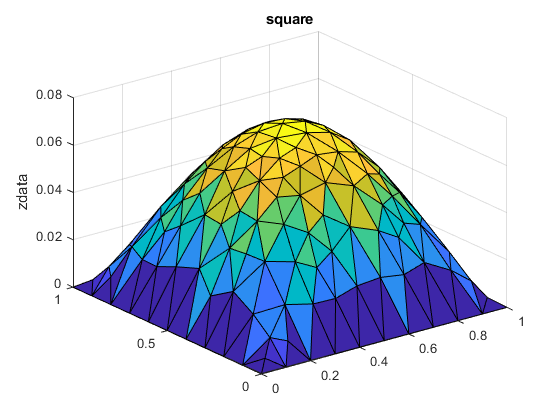

[pSq,eSq,tSq] = initmesh('squareg');
[pSec, eSec, tSec] = initmesh('sectorg');
[pSemiCirc, eSemiCirc, tSemiCirc] = initmesh('semicircleg');

% function u = poisson(p,e,t)
%     n = size(p,2);
%     interior = 1:n;
%     interior(union(e(1,:),e(2,:))) = [];
%     u = zeros(n,1);
%
%     [A,b] = poisson_init(p,e,t);
%     u(interior) = A\b;
% end

u = poisson(pSq,eSq,tSq);
mypdeplot(pSq,eSq,tSq,"square",u)

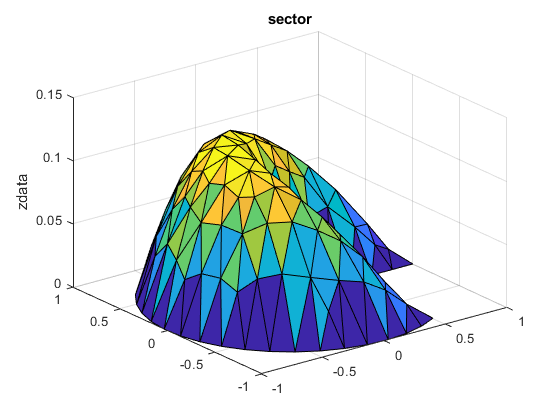



u = poisson(pSec, eSec, tSec);
mypdeplot(pSec, eSec, tSec,"sector",u)

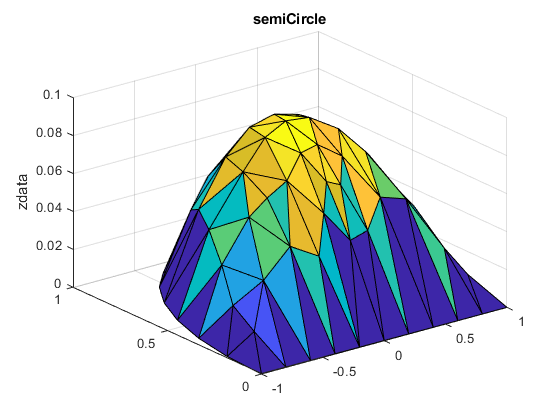


u = poisson(pSemiCirc, eSemiCirc, tSemiCirc);
mypdeplot(pSemiCirc, eSemiCirc, tSemiCirc,"semiCircle",u)

# Adaptive poisson solver

We want to refine the mesh where is is the most necessary. There are many different rules which can be followed, for example in the lecture we discussed the red-green nodes stategie with a local error estimate.

In this exercise sheet we also have a local error for a traingle $t_k$ given by


$$\sum_{t_l \;\textrm{is}\;\textrm{neighbour}\;\textrm{of}\;t_k } \;|S_{\textrm{kl}} |^{2\;} |\nabla u_{h,k} \left(s_{\textrm{kl}} \right)-\nabla \;u_{h,l} \left(s_{\textrm{kl}} \right)|^2$$


This error is calculated for the whole geometry and stored in a vector with the function `poisson_error.m (See end of the PDF). `The mesh is refined till the total error is smaller then `tol = 0.1`

nt = 328

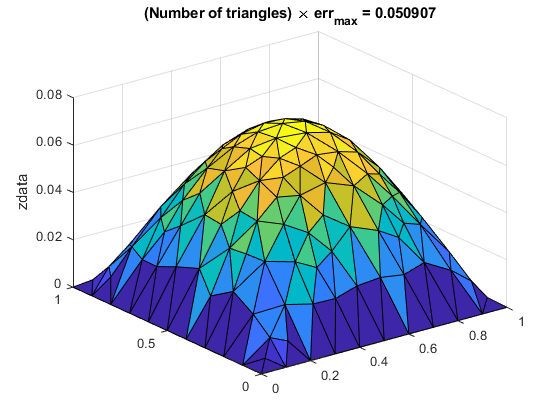


refine_indices =

  1×0 empty double row vector



tol = 0.1;

[err_sq, pSq, eSq, tSq] = poisson_adapt('squareg',tol);

nt = 243

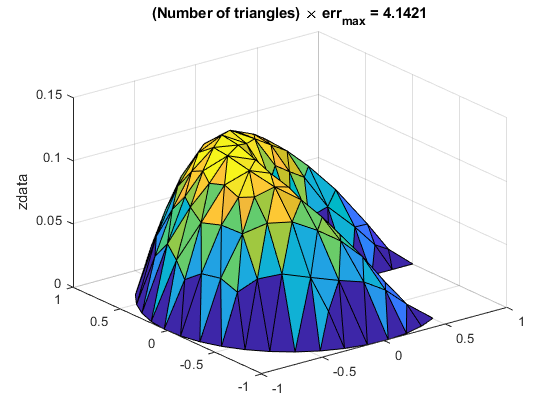

refine_indices =      2     3     4     5     7     8    11    12    31    32    33    40    50    52    63    65    66    68    70    72    74    75    76    81    82    92    98    99   101   106   108   109   110   111   113   114   117   118   119   125   126   127   130   135   136   137   142   143   159   164


nt = 331

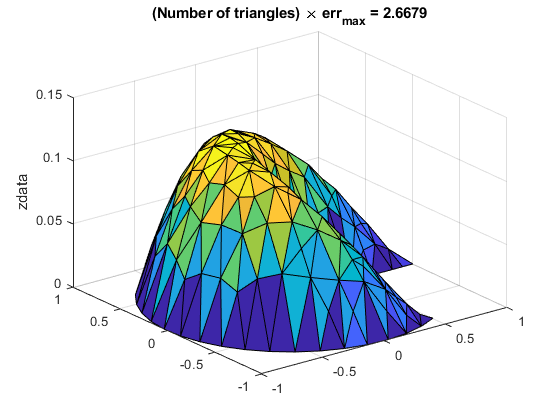

refine_indices =      1     3     4     5    11    13    16    39    40    62    68    80    82    84    94    99   100   108   115   136   141   158   164   167   169   171   177   187   198   204   217   218   224   225   242   244   245   246   248   249   250   261   262   272   273   280   285   289   290   291


nt = 417

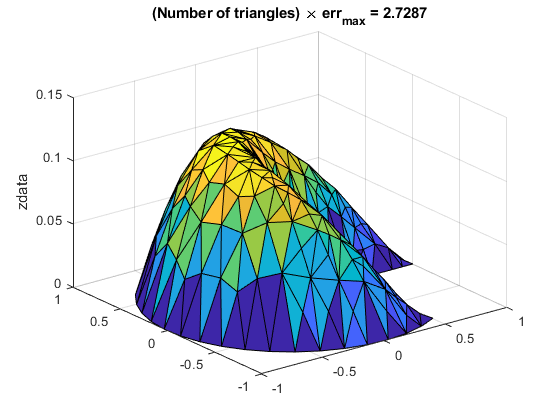

refine_indices =      3     5    21    26    32    63    64    69    71    79    93   109   118   121   124   131   139   147   151   162   163   164   166   178   182   183   191   197   202   209   224   243   245   247   249   259   273   291   333   334   335   338   339   352   376   379   392   393   394   412


nt = 490

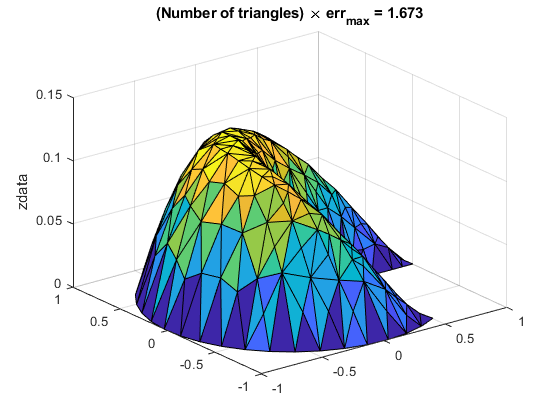

refine_indices =      1     5     6     7     8    88    89    94    95    98   110   112   113   160   175   211   234   249   275   277   281   288   316   331   332   333   336   339   377   392   395   419   420   421   456   479   480


nt = 546

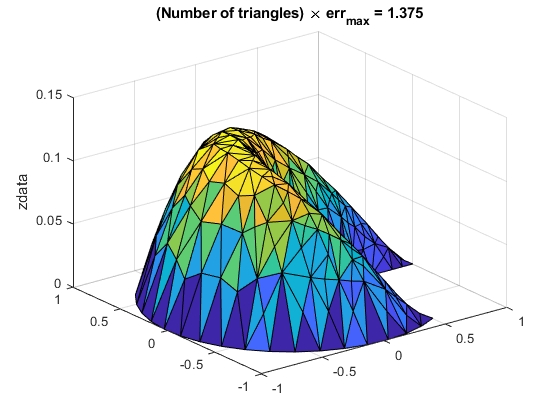

refine_indices =      5    12    19    29    31    40   118   164   200   215   249   259   333   339   359   392   403   420   458   480   494   520   521   532   536   537   538   543


nt = 589

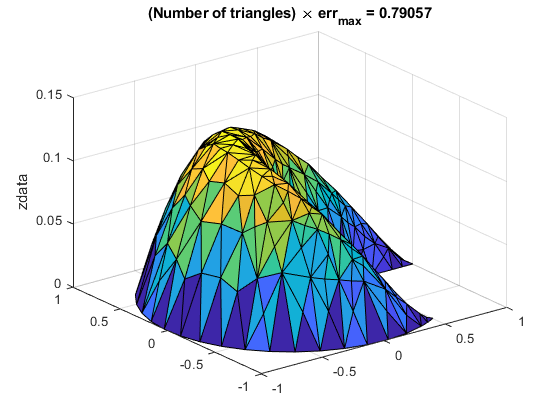

refine_indices =      1     4    25   140   158   198   199   332   339   342   346   397   419   420   480   491   520   532   536   543   573   577   580   581   584   585   589


nt = 632

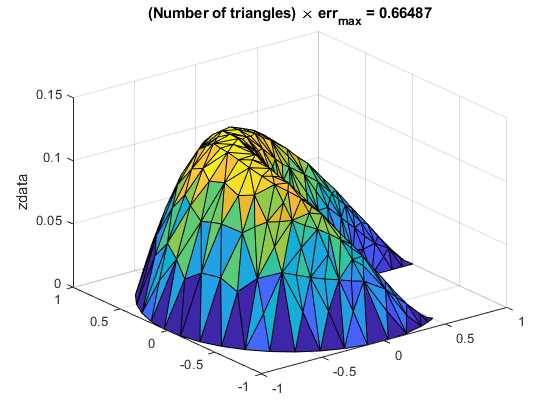

refine_indices =     35   192   241   268   274   284   314   377   471   520   536   544   580   584   588   617   618   619   621   625


nt = 663

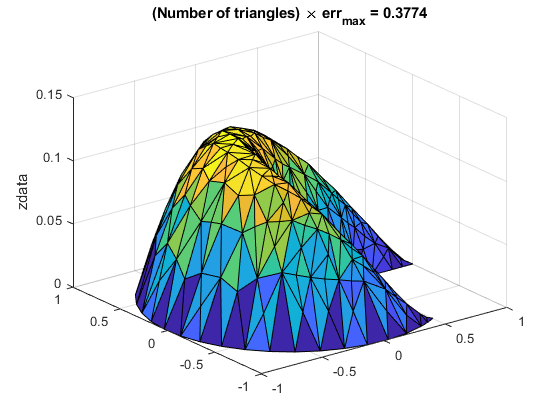

refine_indices =     16   129   172   301   317   366   370   377   573   584   619   621   650   654   658   662


nt = 687

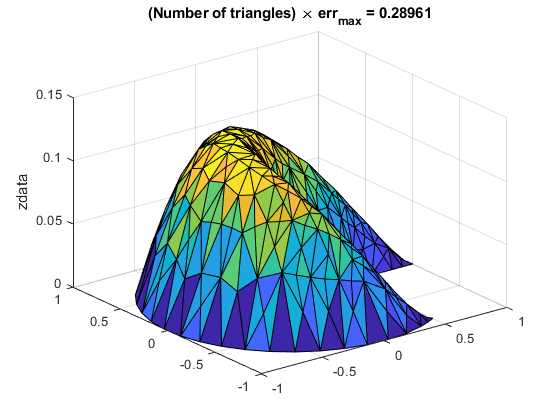

refine_indices =     55    79    96   143   231   422   444   450   625   658   678   682   686


nt = 707

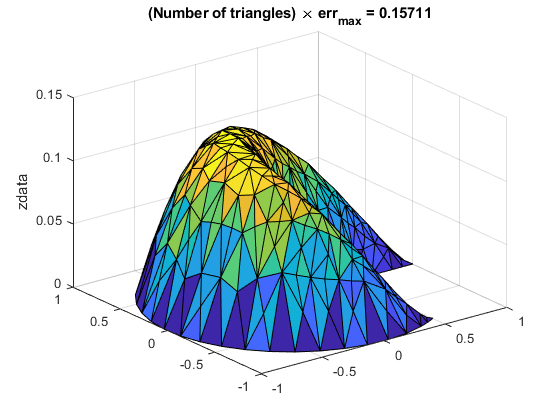

refine_indices =    253   643   656   662   686   704


nt = 716

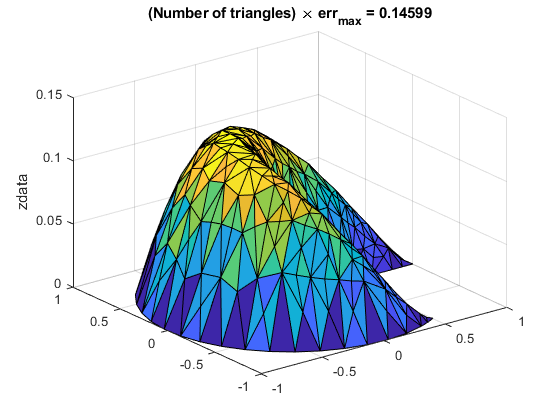

refine_indices =    295   298   616   678   713


nt = 723

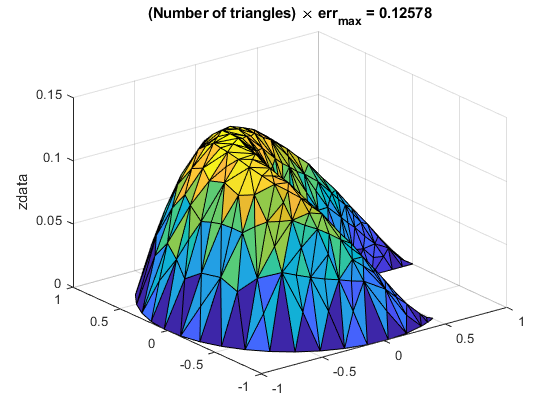

refine_indices =     81   683   702


nt = 729

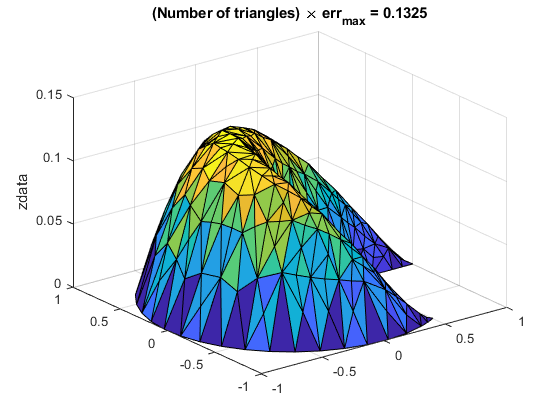

refine_indices =    704   728


nt = 731

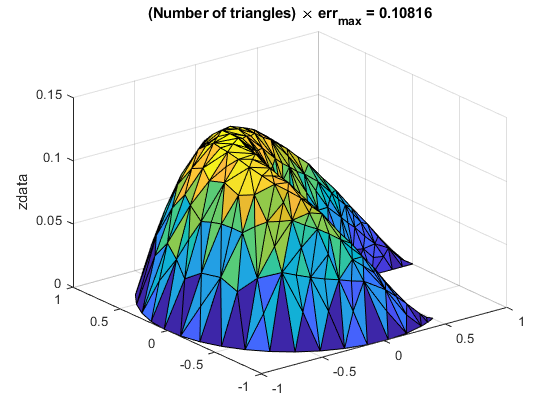

refine_indices =    706   715


nt = 735

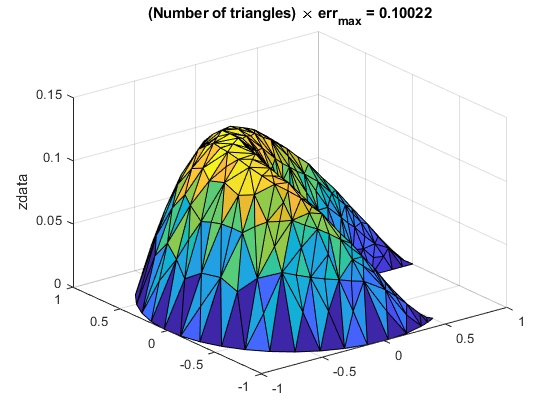

refine_indices = 207

nt = 737

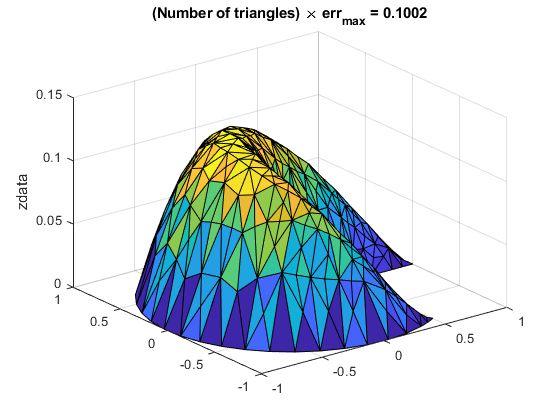

refine_indices = 258

nt = 739

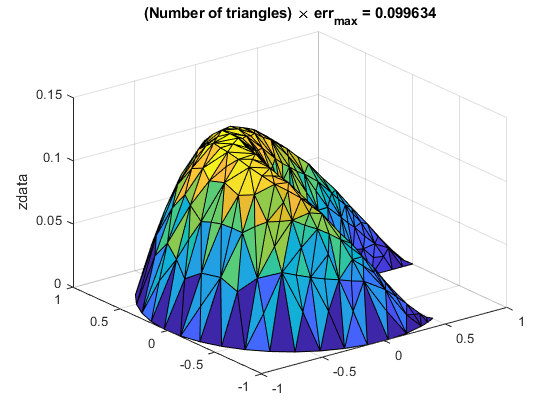


refine_indices =

  1×0 empty double row vector





[err_Sec, pSec, eSec, tSec] = poisson_adapt('sectorg',tol);

nt = 128

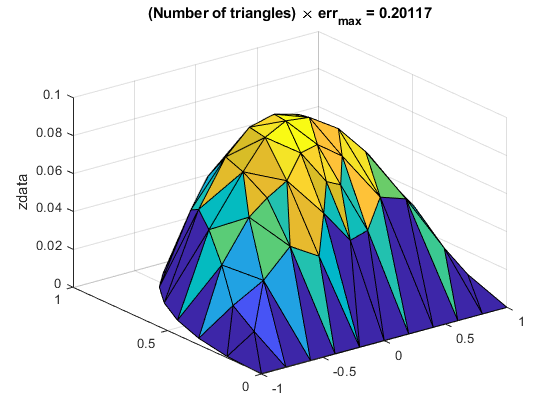

refine_indices =      2     4     8     9    10    19    23    56    64    76    83    86


nt = 144

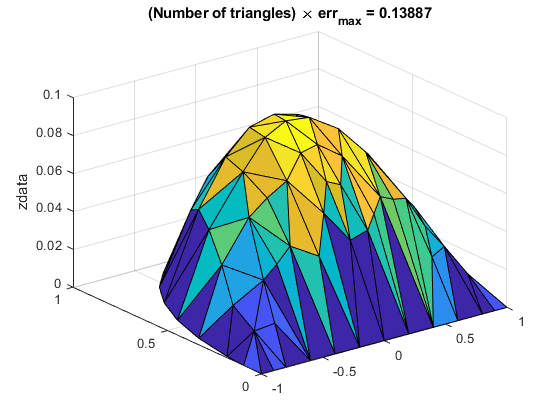

refine_indices =      9    23   129   132


nt = 148

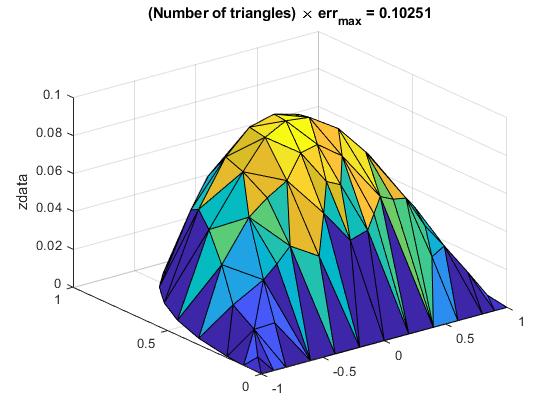

refine_indices =     42    74


nt = 152

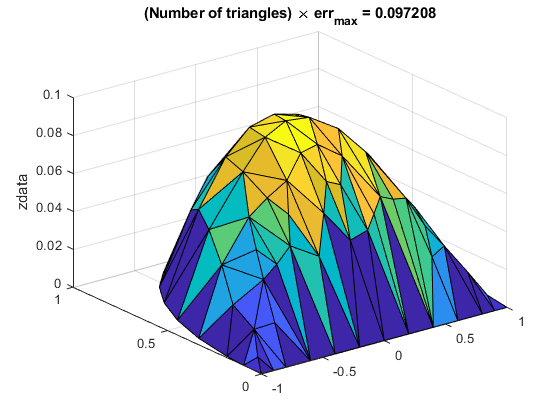


refine_indices =

  1×0 empty double row vector





[err_SemiCirc, pSemiCirc, eSemiCirc, tSemiCirc] = poisson_adapt('semicircleg',tol);

# Functions 

## Poisson init

function [A,b] = poisson_init(p,e,t)
%Computes the stiffness matrix A and the right hand side b
%The matrix A is sparse 
n = size(p,2);
num_elem = size(t,2);
A = sparse(n,n);
b = zeros(n,1);
reference = @(x,y) [1-x-y, x, y];
grad_reference = [-1, 1, 0;...
                  -1, 0, 1];

%in edge e boundaries from p1 to p2 are stored
bound_points = union(e(1,:),e(2,:)); 


%We iterate over all triangle elements and add the components 
%to the assembled matrix
%If it is a boundary we will set it to g(.) = 0
%Calculation according to NUMPDE skript p.104-106
    for t_elem = 1:num_elem
        B = [p(:,t(2,t_elem)) - p(:,t(1,t_elem)), p(:,t(3,t_elem))- p(:,t(1,t_elem))];
        det_B = abs(det(B));
        inv_B = inv(B);
        %Area of the reference element T = 1/2 and Trafo B since const.
        %functions
        A_help = 1/2 * det_B * grad_reference'*inv_B*inv_B'*grad_reference;
        
        
        
        %For each triangular element there are three corners(c1,c2,c3), so the
        %element has an influence at A_(c1,c1) ... A_(c1,c2) ... A(c1,c3)
        %                            A_(c2,c1) ... A_(c2,c2) ... A(c2,c3)
        %                            A_(c3,c1) ... A_(c3,c2) ... A(c3,c3)
        %The reference mapping g from local to global coordinates is
        %defined in t(.)
        
        for i = 1:3
            ih = t(i,t_elem);
            b(ih) = b(ih) + 1/3 * det_B * 1/2;
            %Assemble A
            for j = 1:3
                jh = t(j,t_elem);
                A(ih,jh) = A(ih,jh) + A_help(i,j);

            end
        end

%         for i = 1:3
%             ih = t(i,t_elem);
%             if ~any(ih == bound_points)
%                 %Calculate b
%                 b(ih) = b(ih) + 1/3 * det_B * 1/2;
%                 %Assemble A
%                 for j = 1:3
%                     jh = t(i,t_elem);
%                     if ~any(jh == bound_points)
%                         A(ih,jh) = A(ih,jh) + A_help(i,j);
%                     end
%                 end
%             end
%         end

       
            
    end
    
    A(:,bound_points) = [];
    A(bound_points,:) = [];
    b(bound_points) = [];


end

#### mypdeplot

function mypdeplot(p, e, t, zdata, u)
figure
% Ersten Punkt anhängen, um ein geschlossenes Dreieck zu erhalten
tt = [t(1:3,:); t(1,:)];
P = reshape(p(:,reshape(tt', [], 1)), 2, [], 4);
E = reshape(p(:,reshape(e(1:2,:)', [], 1)), 2, [], 2);

if nargin==3
    hold('on');
    % Plotten der Dreiecke
    plot(squeeze(P(1,:,:))', squeeze(P(2,:,:))', 'b-');
    % Plotten der Randkanten
    plot(squeeze(E(1,:,:))', squeeze(E(2,:,:))', 'r-');
    hold('off');
    axis equal
    axis tight
end

if nargin==5
    trisurf(t(1:3,:)',p(1,:),p(2,:),u)
    zlabel("zdata");
    title(zdata)
   

end

saveas(gcf, zdata+".svg")
end

#### Poisson_error

function err = poisson_error(p,e,t,u)
nt = size(t,2);
err = zeros(1,nt);
for k = 1:(nt-1)
       B_k = [p(:,t(2,k)) - p(:,t(1,k)), p(:,t(3,k)) - p(:,t(1,k))];
       grad_k = inv(B_k)' * [u(t(2,k)) - u(t(1,k)); u(t(3,k))- u(t(1,k))];
       
       for i = 1:3
           %Both properties should be fulfilled
           nb = find(sum((t(1:3,(k+1):nt)==t(i,k)) +...
                         (t(1:3,(k+1):nt)==t(mod(i,3)+1,k)))==2);
           l = k + nb;
           if ~isempty(l)
               B_l = [p(:,t(2,l)) - p(:,t(1,l)), p(:,t(3,l)) - p(:,t(1,l))];
               grad_l = inv(B_l') * [u(t(2,l)) - u(t(1,l)); u(t(3,l))- u(t(1,l))];
               
               
               s_kl = norm(p(1:2,t(i,k)) - p(1:2,t(mod(i,3) + 1,k)));
               err_kl = (s_kl *norm(grad_l - grad_k))^2;
               
               %Update Error
               err(k) = err(k) + err_kl;
               err(l) = err(l) + err_kl; % employ symmetry of error estimator
           end
       end
end
end

#### Poisson_adapt

function [err,p,e,t] = poisson_adapt(g,tol)
[p,e,t] = initmesh(g);

while true
    nt = size(t,2)
    
    u = poisson(p,e,t);
    err = poisson_error(p,e,t,u);


    mypdeplot(p,e,t,'zdata',u)
    title("(Number of triangles) \times err_{max} = " + nt*max(err))
    
    
    refine_indices = find(err>(tol/nt))
    if isempty(refine_indices)
        break;
    end
    [p,e,t] = bisect(g,p,e,t,refine_indices);
end
end

#### Index mapping and check if it is border

% NOTE:
% The task to check if on boundary can be done even more efficient
% following snipplet is one approach, but I forgot to keep track of
% the local coordinates ... since it is not so much more efficient 
% I left it out and noted it at this point.
%             idx = zeros(1,3);
%             put = 1;
%             for i = 1:3
%                 ih = t(i,t_elem);
%                 if ~any(ih == bound_points)
%                     idx(put) = ih;
%                     put = put +1;
%                 end
%             end
%             idx = nonzeros(idx);
%             idx = perms(idx);
%             
%             for i = 1:size(tuples,2)
%                 A(idx(i,1), idx(i,2)) = ...
%                     A(idx(i,1), idx(i,2)) + A_helper;
%             end